# FMCW Data Collect

In this script, we test that the FMCW steering is working as expected. Place a target in a known location and steer across the field of view, should see a peak at the target location.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

For this lab, we use many of the same parameters that were used in previous labs.

% Setup Phaser
fc = 10e9;
prf = 500;
nPulses = 1;
fs = 1e6;
rampbandwidth = 500e6;
[rx,tx,bf,bf_TDD] = setupLabRadar(fc,prf,nPulses,fs,rampbandwidth);
tSweep = double(bf.FrequencyDeviationTime)/1e6;
sweepSlope = rampbandwidth/tSweep;
rr = phased.RangeResponse(RangeMethod="FFT",SampleRate=fs,SweepSlope=sweepSlope);

% Setup the array model for steering
lambda = freq2wavelen(10.7e9);
spacing = lambda/2;
array = phased.ULA(NumElements=8,ElementSpacing=spacing);
elementPosition = array.getElementPosition();

Load the calibration weights which are required for steering the antenna.

load('CalibrationWeights.mat','calibrationweights');

% Setup the capture
nCapture = 10;
steerang = -90:2:90;
nang = length(steerang);
data = cell(nCapture,nang);

Setup an estimated truth range and angle.

truthRange = 1.8;
truthAngle = 0;

Create a plot for the range response.

axesrr = axes(figure);
hold(axesrr,"on");
linerr = plot(axesrr,1,1);
scatrr = scatter(axesrr,1,1);
xlim(axesrr,[0 10]);

Create a plot for the angle response

axesang = axes(figure);
hold(axesang,"on");
lineang = plot(axesang,1,1);

Capture data.

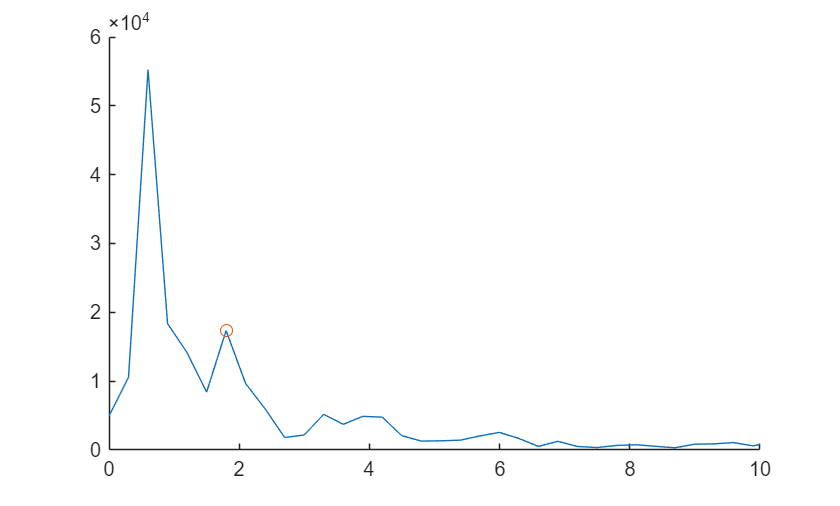

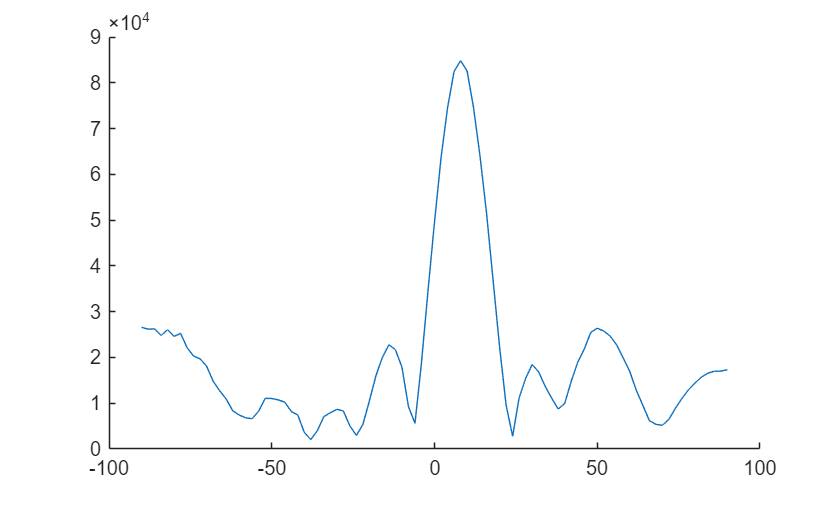

captureTransmitWaveform(rx,tx,bf);
tseed = tic;
t = zeros(1,nCapture);
for iCapture = 1:nCapture
    angdata = zeros(1,nang);
    for iAng = 1:nang
        % Steer the analog beamformers
        cang = steerang(iAng);
        steerweights = steervec(elementPosition/freq2wavelen(fc),[cang;0]);
        analogsteer = analogWeightsCalAdjustment([steerweights(1:4) steerweights(5:8)],calibrationweights.AnalogWeights);
        setAnalogBfWeights(bf,analogsteer);

        % Trigger burst pulse
        bf.Burst=false;bf.Burst=true;bf.Burst=false;

        % Capture pulse period
        rxdata = rx();

        % Combine channels
        rxdata = applyDigitalCalWeights(rxdata);
        
        % get range response
        [resp,range] = rr(rxdata);

        % Get the index of the range closest to target
        [~,tidx] = min(abs(range-truthRange));

        % Update the range response plot
        set(linerr,'XData',range,'YData',abs(resp));
        set(scatrr,'XData',truthRange,'YData',abs(resp(tidx)));
        drawnow

        % Save the response for the angle
        angdata(iAng) = abs(resp(tidx));
    end

    % Update the angle response plot
    set(lineang,'XData',steerang,'YData',angdata);
    drawnow;

    t(iCapture) = toc(tseed);
end


% Create configuration
tSweep = double(bf.FrequencyDeviationTime)/1e6;
tstartsweep = bf_TDD.Ch0On;
tframe = bf_TDD.FrameLength / 1e3;
config = FmcwTrackingConfig(prf,nPulses,fc,fs,tSweep,rampbandwidth,steerang,tstartsweep,tframe);

% Save data, configuration, and truth values for future analysis
save('datacapture_0_deg_3_m_swapsteer.mat','data','config','truthRange','truthAngle','t');